# regression

d = 100;
beta = 1e-1;
X = rand(1,d);
w = randn;
b = randn;
t = w'*X+b+beta*randn(1,d);
x = linspace(min(X),max(X),d);   % test data

## RVM regression by Mackay fix point update

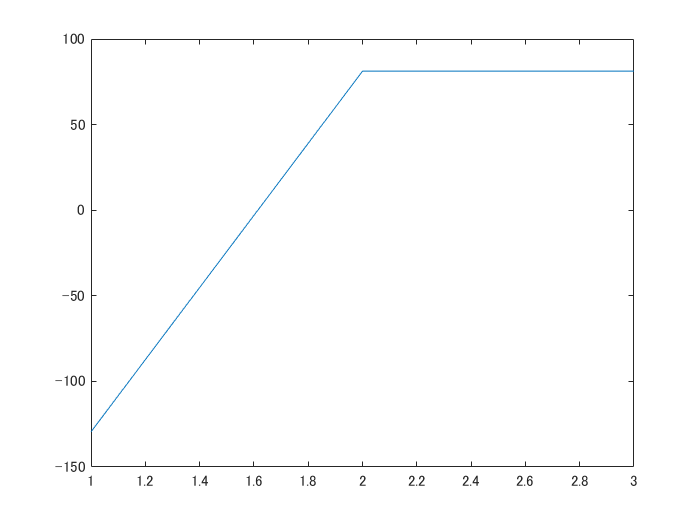

[model,llh] = rvmRegFp(X,t);
plot(llh);

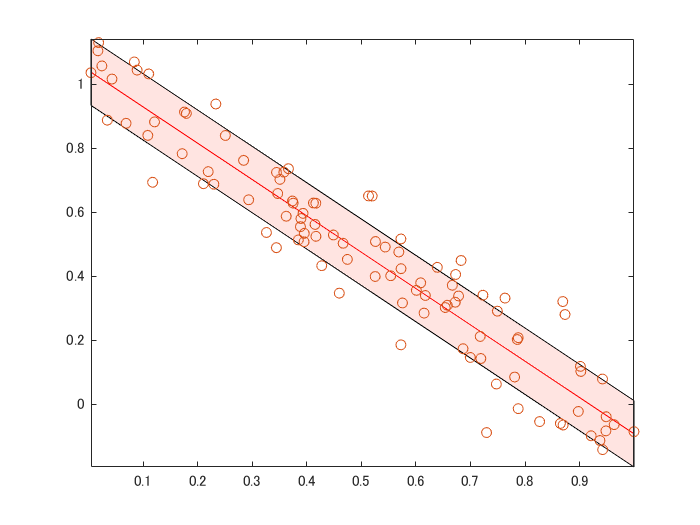

[y, sigma] = linRegPred(model,x,t);
figure
plotCurveBar(x,y,sigma);
hold on;
plot(X,t,'o');
hold off